# BCI project procedure - Preprocessing (Without ICA)

**1) Rejection of bad EEG channels for each run and each subject**

For this first part, the bad EEG channels have been rejected for each run and each subject. First, it is important to select which are the subjects that are going to be used in this project among the fifteen healthy subjects that have participated in this study. On this occasion, the subjects are S1, S2, S3, S6, S7, S9, S11, S13.

It is interesting to mention that the data available for each subject consists of ten runs with 6 trials per run and the EEG signals were recorded from 61 channels covering frontal, central, parietal, and temporal areas. 

We have also chosen to show how long the calculations take, considering that the amount of data is not insignificant and thus, a good run time is desired.

subject_list= ["S1", "S2", "S3", "S6", "S7", "S9", "S11", "S13"];
addpath('functions')
waitfor(msgbox("In the next step, please select the path where eeglab is found", 'EEGLAB path selection'));
    eegpath=uigetdir;
    addpath(eegpath)
    waitfor(msgbox("Finally, please select your loc file", 'Loc file selection'));
    [locs,locpath]=uigetfile('*.loc', 'Pick a channel location file');
    locpath=strrep(locpath,'\','\\'); %for windows
    locs=append(locpath,locs);

**NOTES: **

**Make sure the folder containing your 'data' folder is added to path. **

**For further info, check each function file where the procedure will be explained in depth.**

**Please be patient. Complete run time with automated ICA rejection will take approximately 2-3 h on most computers.   **

## D1. Artifacted channels for each subject and run

Above, we chose our initial parameters. Now we will preprocess. The first function we call selects the bad channels for each run and saves them to a .mat file.

tstart=tic;
d1_bad_channels(subject_list,true,locs);

Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\vctrf\eeg_options.m
Retrieving plugin versions from server...
Retreiving download statistics...
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel)
EEGLAB: adding "clean_rawdata" v2.4 (see >> help eegplugin_clean_rawdata) - new version 2.6 available
EEGLAB: adding "dipfit" v4.2 (see >> help eegplugin_dipfit) - new version 4.3 available
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt)


pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'D:\\Universidad\\Master\\Q2\\HMI\\Lab 1\\Version definitiva\\loc61eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (164617) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 0

pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'D:\\Universidad\\Master\\Q2\\HMI\\Lab 1\\Version definitiva\\loc61eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (165417) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 0

pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'D:\\Universidad\\Master\\Q2\\HMI\\Lab 1\\Version definitiva\\loc61eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (165753) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 0

pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'D:\\Universidad\\Master\\Q2\\HMI\\Lab 1\\Version definitiva\\loc61eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (165368) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 0

pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'D:\\Universidad\\Master\\Q2\\HMI\\Lab 1\\Version definitiva\\loc61eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (165462) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 0

pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'D:\\Universidad\\Master\\Q2\\HMI\\Lab 1\\Version definitiva\\loc61eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (167058) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 0

pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'D:\\Universidad\\Master\\Q2\\HMI\\Lab 1\\Version definitiva\\loc61eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (167574) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 0

pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'D:\\Universidad\\Master\\Q2\\HMI\\Lab 1\\Version definitiva\\loc61eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (168122) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 0

pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'D:\\Universidad\\Master\\Q2\\HMI\\Lab 1\\Version definitiva\\loc61eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (165116) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 0

pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'D:\\Universidad\\Master\\Q2\\HMI\\Lab 1\\Version definitiva\\loc61eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (165547) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 0

pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'D:\\Universidad\\Master\\Q2\\HMI\\Lab 1\\Version definitiva\\loc61eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (164617) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 0

pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'D:\\Universidad\\Master\\Q2\\HMI\\Lab 1\\Version definitiva\\loc61eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (165417) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 0

pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'D:\\Universidad\\Master\\Q2\\HMI\\Lab 1\\Version definitiva\\loc61eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (165753) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 0

pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'D:\\Universidad\\Master\\Q2\\HMI\\Lab 1\\Version definitiva\\loc61eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (165368) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 0

pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'D:\\Universidad\\Master\\Q2\\HMI\\Lab 1\\Version definitiva\\loc61eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (165462) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 0

pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'D:\\Universidad\\Master\\Q2\\HMI\\Lab 1\\Version definitiva\\loc61eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (167058) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 0

pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'D:\\Universidad\\Master\\Q2\\HMI\\Lab 1\\Version definitiva\\loc61eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (167574) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 0

pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'D:\\Universidad\\Master\\Q2\\HMI\\Lab 1\\Version definitiva\\loc61eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (168122) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 0

pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'D:\\Universidad\\Master\\Q2\\HMI\\Lab 1\\Version definitiva\\loc61eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (165116) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 0

pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'D:\\Universidad\\Master\\Q2\\HMI\\Lab 1\\Version definitiva\\loc61eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (165547) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 0

pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'D:\\Universidad\\Master\\Q2\\HMI\\Lab 1\\Version definitiva\\loc61eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (167997) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 0

pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'D:\\Universidad\\Master\\Q2\\HMI\\Lab 1\\Version definitiva\\loc61eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (165498) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 0

pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'D:\\Universidad\\Master\\Q2\\HMI\\Lab 1\\Version definitiva\\loc61eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (166607) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 0

pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'D:\\Universidad\\Master\\Q2\\HMI\\Lab 1\\Version definitiva\\loc61eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (166656) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 0

pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'D:\\Universidad\\Master\\Q2\\HMI\\Lab 1\\Version definitiva\\loc61eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (166435) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 0

pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'D:\\Universidad\\Master\\Q2\\HMI\\Lab 1\\Version definitiva\\loc61eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (165332) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 0

pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'D:\\Universidad\\Master\\Q2\\HMI\\Lab 1\\Version definitiva\\loc61eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (166763) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 0

pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'D:\\Universidad\\Master\\Q2\\HMI\\Lab 1\\Version definitiva\\loc61eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (166307) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 0

pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'D:\\Universidad\\Master\\Q2\\HMI\\Lab 1\\Version definitiva\\loc61eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (166976) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 0

pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'D:\\Universidad\\Master\\Q2\\HMI\\Lab 1\\Version definitiva\\loc61eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (166573) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 0

pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'D:\\Universidad\\Master\\Q2\\HMI\\Lab 1\\Version definitiva\\loc61eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (164617) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 0

pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'D:\\Universidad\\Master\\Q2\\HMI\\Lab 1\\Version definitiva\\loc61eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (165417) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 0

pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'D:\\Universidad\\Master\\Q2\\HMI\\Lab 1\\Version definitiva\\loc61eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (165753) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 0

pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'D:\\Universidad\\Master\\Q2\\HMI\\Lab 1\\Version definitiva\\loc61eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (165368) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 0

pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'D:\\Universidad\\Master\\Q2\\HMI\\Lab 1\\Version definitiva\\loc61eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (165462) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 0

pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'D:\\Universidad\\Master\\Q2\\HMI\\Lab 1\\Version definitiva\\loc61eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (167058) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 0

pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'D:\\Universidad\\Master\\Q2\\HMI\\Lab 1\\Version definitiva\\loc61eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (167574) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 0

pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'D:\\Universidad\\Master\\Q2\\HMI\\Lab 1\\Version definitiva\\loc61eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (168122) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 0

pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'D:\\Universidad\\Master\\Q2\\HMI\\Lab 1\\Version definitiva\\loc61eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (165116) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 0

pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'D:\\Universidad\\Master\\Q2\\HMI\\Lab 1\\Version definitiva\\loc61eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (165547) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 0

pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'D:\\Universidad\\Master\\Q2\\HMI\\Lab 1\\Version definitiva\\loc61eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (164617) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 0

pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'D:\\Universidad\\Master\\Q2\\HMI\\Lab 1\\Version definitiva\\loc61eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (165417) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 0

pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'D:\\Universidad\\Master\\Q2\\HMI\\Lab 1\\Version definitiva\\loc61eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (165753) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 0

pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'D:\\Universidad\\Master\\Q2\\HMI\\Lab 1\\Version definitiva\\loc61eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (165368) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 0

pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'D:\\Universidad\\Master\\Q2\\HMI\\Lab 1\\Version definitiva\\loc61eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (165462) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 0

pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'D:\\Universidad\\Master\\Q2\\HMI\\Lab 1\\Version definitiva\\loc61eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (167058) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 0

pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'D:\\Universidad\\Master\\Q2\\HMI\\Lab 1\\Version definitiva\\loc61eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (167574) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 0

pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'D:\\Universidad\\Master\\Q2\\HMI\\Lab 1\\Version definitiva\\loc61eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (168122) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 0

pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'D:\\Universidad\\Master\\Q2\\HMI\\Lab 1\\Version definitiva\\loc61eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (165116) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 0

pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'D:\\Universidad\\Master\\Q2\\HMI\\Lab 1\\Version definitiva\\loc61eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (165547) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 0

pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'D:\\Universidad\\Master\\Q2\\HMI\\Lab 1\\Version definitiva\\loc61eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (164617) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 0

pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'D:\\Universidad\\Master\\Q2\\HMI\\Lab 1\\Version definitiva\\loc61eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (165417) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 0

pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'D:\\Universidad\\Master\\Q2\\HMI\\Lab 1\\Version definitiva\\loc61eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (165753) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 0

pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'D:\\Universidad\\Master\\Q2\\HMI\\Lab 1\\Version definitiva\\loc61eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (165368) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 0

pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'D:\\Universidad\\Master\\Q2\\HMI\\Lab 1\\Version definitiva\\loc61eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (165462) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 0

pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'D:\\Universidad\\Master\\Q2\\HMI\\Lab 1\\Version definitiva\\loc61eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (167058) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 0

pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'D:\\Universidad\\Master\\Q2\\HMI\\Lab 1\\Version definitiva\\loc61eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (167574) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 0

pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'D:\\Universidad\\Master\\Q2\\HMI\\Lab 1\\Version definitiva\\loc61eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (168122) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 0

pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'D:\\Universidad\\Master\\Q2\\HMI\\Lab 1\\Version definitiva\\loc61eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (165116) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 0

pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'D:\\Universidad\\Master\\Q2\\HMI\\Lab 1\\Version definitiva\\loc61eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (165547) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 0

pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'D:\\Universidad\\Master\\Q2\\HMI\\Lab 1\\Version definitiva\\loc61eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (165417) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 0

pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'D:\\Universidad\\Master\\Q2\\HMI\\Lab 1\\Version definitiva\\loc61eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (165753) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 0

pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'D:\\Universidad\\Master\\Q2\\HMI\\Lab 1\\Version definitiva\\loc61eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (165368) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 0

pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'D:\\Universidad\\Master\\Q2\\HMI\\Lab 1\\Version definitiva\\loc61eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (165462) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 0

pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'D:\\Universidad\\Master\\Q2\\HMI\\Lab 1\\Version definitiva\\loc61eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (167058) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 0

pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'D:\\Universidad\\Master\\Q2\\HMI\\Lab 1\\Version definitiva\\loc61eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (167574) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 0

pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'D:\\Universidad\\Master\\Q2\\HMI\\Lab 1\\Version definitiva\\loc61eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (168122) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 0

pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'D:\\Universidad\\Master\\Q2\\HMI\\Lab 1\\Version definitiva\\loc61eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (165116) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 0

pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'D:\\Universidad\\Master\\Q2\\HMI\\Lab 1\\Version definitiva\\loc61eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (165547) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 0

pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'D:\\Universidad\\Master\\Q2\\HMI\\Lab 1\\Version definitiva\\loc61eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (166257) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 0

pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'D:\\Universidad\\Master\\Q2\\HMI\\Lab 1\\Version definitiva\\loc61eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (168385) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 0

pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'D:\\Universidad\\Master\\Q2\\HMI\\Lab 1\\Version definitiva\\loc61eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (166031) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 0

pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'D:\\Universidad\\Master\\Q2\\HMI\\Lab 1\\Version definitiva\\loc61eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (168179) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 0

pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'D:\\Universidad\\Master\\Q2\\HMI\\Lab 1\\Version definitiva\\loc61eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (167997) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 0

pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'D:\\Universidad\\Master\\Q2\\HMI\\Lab 1\\Version definitiva\\loc61eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (165498) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 0

pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'D:\\Universidad\\Master\\Q2\\HMI\\Lab 1\\Version definitiva\\loc61eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (166607) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 0

pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'D:\\Universidad\\Master\\Q2\\HMI\\Lab 1\\Version definitiva\\loc61eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (166656) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 0

pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'D:\\Universidad\\Master\\Q2\\HMI\\Lab 1\\Version definitiva\\loc61eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (166435) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 0

pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'D:\\Universidad\\Master\\Q2\\HMI\\Lab 1\\Version definitiva\\loc61eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (165332) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 0

pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'D:\\Universidad\\Master\\Q2\\HMI\\Lab 1\\Version definitiva\\loc61eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (166763) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 0

tEnd = toc(tstart);
 fprintf('Elapsed time is %d minutes and %f seconds\n', floor(tEnd/60), rem(tEnd,60));

Elapsed time is 37 minutes and 48.832182 seconds


clear EEG ALLEEG CURRENTSET ALLCOM
tstart=tic;
d1_bad_channels(subject_list,false,locs);
tEnd = toc(tstart);
fprintf('Elapsed time is %d minutes and %f seconds\n', floor(tEnd/60), rem(tEnd,60));

Elapsed time is 2 minutes and 44.630557 seconds


A table has been created with the artifacted channels, the ones considered as bad channels, for each subject and run.

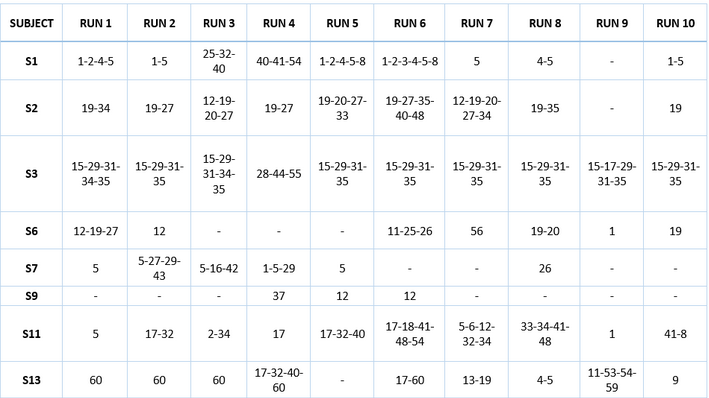

As can be observed in the table above, the channels for each run for each subject considered “bad channels” are shown. The cells with no “bad channel” are empty (-). It is important to mention that each channel has associated a label which determine the EEG electrode position. Some subjects may seem more interesting to take a second to mention on as for instance the subject number 9 which has almost no “bad channels” revealing that artifacts were not recorded. Also, subject number 3 shows some channels that are repeated in almost all the runs or a more heterogeneous distribution of bad channels during the different runs as subject 11 or subject 13. 

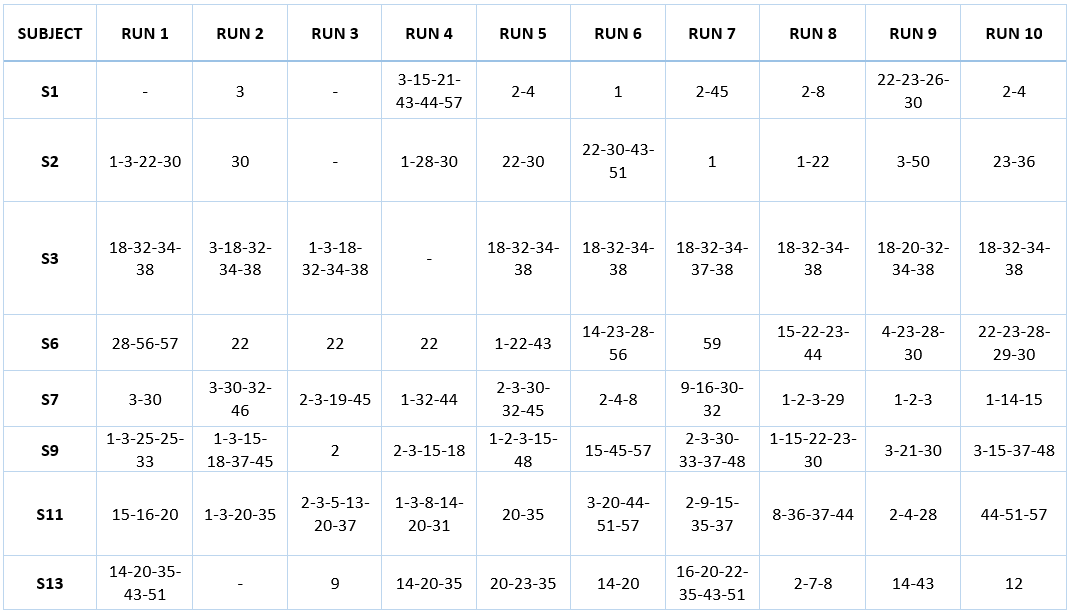

**2) Rejection of bad trials for each movement and subject**

Once the bad channels have been selected, we run the second function to find the bad trials. It takes the movement code as an argument, so we run it for each movement. In this case, the movement classes are:

- Elbow flexion (1536)

- Hand opening (1541)

Below, the different runs for the bad trials, with the different arguments, are coded. The variations calculated have been done with and without ICA and with and without automatic movement detection, in all of the possible permutations, thus yielding four different solutions for each movement type.

%returns the matrix, now with bad trials marked too
tstart=tic;
d2_bad_trials(subject_list,1536,true,true)

Calculating bad trials for Elbow flexion
Elapsed time is 0.288367 seconds.
Elapsed time is 26.959647 seconds.
Elapsed time is 28.339231 seconds.
Elapsed time is 28.358377 seconds.
Elapsed time is 52.497312 seconds.
Elapsed time is 53.902050 seconds.
Elapsed time is 53.919429 seconds.
Elapsed time is 78.411954 seconds.
Elapsed time is 79.669367 seconds.
Elapsed time is 79.690659 seconds.
Elapsed time is 104.463993 seconds.
Elapsed time is 105.857880 seconds.
Elapsed time is 105.875568 seconds.
Elapsed time is 131.035797 seconds.
Elapsed time is 132.441619 seconds.
Elapsed time is 132.459129 seconds.
Elapsed time is 158.138786 seconds.
Elapsed time is 159.561257 seconds.
Elapsed time is 159.578785 seconds.
Elapsed time is 185.904918 seconds.
Elapsed time is 187.332492 seconds.
Elapsed time is 187.352946 seconds.
Elapsed time is 213.987681 seconds.
Elapsed time is 215.423177 seconds.
Elapsed time is 215.440108 seconds.
Elapsed time is 242.948611 seconds.
Elapsed time is 244.384557 seconds

Elapsed time is 244.402869 seconds.


tEnd = toc(tstart);
 fprintf('Elapsed time is %d minutes and %f seconds\n', floor(tEnd/60), rem(tEnd,60));
tstart=tic;
d2_bad_trials(subject_list,1536,false,true)
tEnd = toc(tstart);
 fprintf('Elapsed time is %d minutes and %f seconds\n', floor(tEnd/60), rem(tEnd,60));

tstart=tic
d2_bad_trials(subject_list,1536,true,false)
tEnd = toc(tstart);
 fprintf('Elapsed time is %d minutes and %f seconds\n', floor(tEnd/60), rem(tEnd,60));
tstart=tic;
d2_bad_trials(subject_list,1536,false,false)
tEnd = toc(tstart);
 fprintf('Elapsed time is %d minutes and %f seconds\n', floor(tEnd/60), rem(tEnd,60));

tstart=tic;
d2_bad_trials(subject_list,1541,true,true)
tEnd = toc(tstart);
 fprintf('Elapsed time is %d minutes and %f seconds\n', floor(tEnd/60), rem(tEnd,60));
tstart=tic;
d2_bad_trials(subject_list,1541,false,true)
tEnd = toc(tstart);
 fprintf('Elapsed time is %d minutes and %f seconds\n', floor(tEnd/60), rem(tEnd,60));

tstart=tic
d2_bad_trials(subject_list,1541,true,false)
tEnd = toc(tstart);
 fprintf('Elapsed time is %d minutes and %f seconds\n', floor(tEnd/60), rem(tEnd,60));
tstart=tic;
d2_bad_trials(subject_list,1541,false,false)
tEnd = toc(tstart);
 fprintf('Elapsed time is %d minutes and %f seconds\n', floor(tEnd/60), rem(tEnd,60));

## D2. Percentage of good (artifact-free) trials for each subject and movement class

Now we will want to display the data. If the variables are not loaded, we will load them from the file created in the previous step.

if exist("bad_trials_1536",'var')==0
    bad_trials_1536=load("bad_trials_1536.mat","matrix_detrend");
    bad_trials_1536=bad_trials_1536.matrix_detrend;
end
if exist("bad_trials_1541",'var')==0
    bad_trials_1541=load("bad_trials_1541.mat","matrix_detrend");
    bad_trials_1541=bad_trials_1541.matrix_detrend;
end

Next, we create a table with the percentage of good trials for all channels. Considering we saved the bad trials and runs as NaNs, the following form creates and displays a table in Matlab's table format.

%create a table of good trial percentage per user/movement
T=[];
for subject=1:length(bad_trials_1536(1,1,1,:))
        T(subject,1)=nnz(~isnan(bad_trials_1536(:,:,:,subject)))/numel(bad_trials_1536(:,:,:,subject));
        T(subject,2)=nnz(~isnan(bad_trials_1541(:,:,:,subject)))/numel(bad_trials_1541(:,:,:,subject));

end
T=round(T,4)*100;
T=array2table(T,"RowNames",subject_list,"VariableNames",["Elbow Flexion", "Hand Opening"]);
disp(T)

In the table above, it can be seen the percentage of artifact-free trials for each subject for all the channels depending on the movement class. On one hand, regarding the elbow flexion, the subject 2 is the one presenting a lower rate of artifact-free trials while the subject 7 present the better result. On the other hand, as refers to the hand opening, the subject 13 presents a lower percentage while the subject 9 presents the higher percentage of artifact-free trials. 

Then we create a table for Cz (channel 30) only, in order to compare our results with the example given.

T30=[];
for subject=1:length(bad_trials_1536(1,1,1,:))
        T30(subject,1)=nnz(~isnan(bad_trials_1536(30,:,:,subject)))/numel(bad_trials_1536(30,:,:,subject));
        T30(subject,2)=nnz(~isnan(bad_trials_1541(30,:,:,subject)))/numel(bad_trials_1541(30,:,:,subject));

end
T30=round(T30,4)*100;
T30=array2table(T30,"RowNames",subject_list,"VariableNames",["Elbow Flexion", "Hand Opening"]);
disp(T30)

Although, for hand opening, subject 1's results are the same, subject 2 has a slightly lower good trial rate in the given data. This could be due to the filtering and processing methodology, and was therefore not considered to be an issue.

## D3. Plots

In this section, the average (considering only the good trials) for channel Cz for each subject and class movement has been represented. Moreover, the grand-mean average (average of all subjects) of trials for Cz and each movement class.

ho_30=squeeze(mean(bad_trials_1541(30,:,:,:),3,'omitnan'));
ef_30=squeeze(mean(bad_trials_1536(30,:,:,:),3,'omitnan'));

ica1536=load("bad_trials_1536_with_ica.mat");
ica1541=load("bad_trials_1541_with_ica.mat");

ho_30_ica=squeeze(mean(ica1541.matrix_detrend(30,:,:,:),3,'omitnan'));
ef_30_ica=squeeze(mean(ica1536.matrix_detrend(30,:,:,:),3,'omitnan'));
fm=512;
t=-2.5+1/fm:1/fm:(4352-2.5*512)/fm;
figure(6)
tiledlayout('flow','TileSpacing','compact','Padding','compact')
for i=1:8

    nexttile
    hold on
    plot(t,ho_30(:,i))
    plot(t,ho_30_ica(:,i))  
    xline(0)
    hold off
    legend('Normal','ICA')
end

%%%%%%%
figure
tiledlayout('flow','TileSpacing','compact','Padding','compact')
for i=1:8

    nexttile
    hold on
    plot(t,ef_30(:,i))
    plot(t,ef_30_ica(:,i))
    xline(0)
    hold off
    legend('Normal','ICA')
end
gm_average_30=mean(ho_30,2);
gm_30_ica=mean(ho_30_ica,2);
figure
plot(t,gm_average_30)
hold on
plot(t,gm_30_ica)
xline(-2)
xline(0)
legend('Normal','ICA')

hold off

